out1 = sim("ControlledV1.slx");

Stepdata = out1.ScopeData1;
time = out1.tout;
Step_input = out1.ScopeData1.signals(1).values;
Step_output = out1.ScopeData1.signals(2).values;

Sindata = out1.ScopeData2

Sindata = struct with fields:
         time: []
      signals: [1×2 struct]
    blockName: 'ControlledV1/Scope3'


Sin_input = out1.ScopeData2.signals(1).values;
Sin_output = out1.ScopeData2.signals(2).values;

Rampdata = out1.ScopeData3

Rampdata = struct with fields:
         time: []
      signals: [1×2 struct]
    blockName: 'ControlledV1/Scope5'


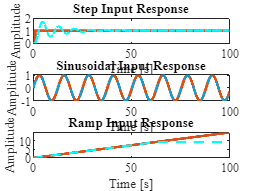

Ramp_input = out1.ScopeData3.signals(1).values;
Ramp_output = out1.ScopeData3.signals(2).values;

subplot(3,1,1)
plot(time,Step_input,LineWidth=2,Color='#D95319')
hold on
plot(time,Step_output,LineWidth=1.5,LineStyle="-.",Color='#00FFFF')
xlim([0 100])
xlabel({'Time [s]',' '})
ylabel('Amplitude')
title('Step Input Response')
fontname('Times New Roman',11)
hold on

subplot(3,1,2)
plot(time,Sin_input,LineWidth=2,Color='#D95319')
hold on
plot(time,Sin_output,LineWidth=1.5,LineStyle="--",Color='#0F9ED5')
xlim([0 100])
xlabel('Time [s]')
ylabel('Amplitude')
title('Sinusoidal Input Response')
fontname('Times New Roman',11)
hold on

subplot(3,1,3)
plot(time,Ramp_input,LineWidth=2,Color='#D95319')
hold on
plot(time,Ramp_output,LineWidth=1.5,LineStyle="--",Color='#00FFFF')
xlim([0 100])
xlabel('Time [s]')
ylabel('Amplitude')
title('Ramp Input Response')
fontname('Times New Roman',11)
hold off


Controlled = stepinfo(Step_output,time)

Controlled = struct with fields:
         RiseTime: 1.413298175172457
    TransientTime: 42.279553228282474
     SettlingTime: 42.279553228282474
      SettlingMin: 0.517560692736081
      SettlingMax: 1.694085536933067
        Overshoot: 69.416113994386293
       Undershoot: 0
             Peak: 1.694085536933067
         PeakTime: 4.772588685090224
